## Señal modulada BPSK

transmision por desplazamiento de fase binaria, consiste endesplazar la fase de una portadora senoidal de 0 a 180° con una señal binaria unipolar, es una señalizacion PM con una forma de onda digital.

es una Señal DSB-SC con una forma de onda digital polar.

La señal BPSK esta dada por S(t)


$$s\left(t\right)=A_{c\;} \;\cos \;\left\lbrack \omega_c \;t+D_p \;m\left(t\right)\;\right\rbrack$$


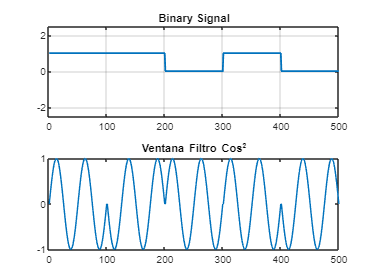

% The number of bits to send - Frame Length
N               =                 1;
time0           =            1:1:500;
% Sampling rate - This will define the resoultion
fs              =             100;
% Generate a random bit stream
bit_stream      =   round(rand(1,N));
bpsk_signal = BPSK([1 0 1 1 0],2);
plot(time0, bpsk_signal);
title('Ventana Filtro Cos^2');

## Filtro formador de Coseno Elevado

% para recortar la señal y solo agarrar DBLSC
time_filter = 0:1:500;
time_filter_2 = 0:1:300;
filtro_rsine = rcosine(1,50);

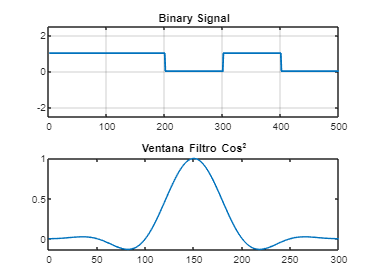

%VENTANA FILTRO
plot(time_filter_2, filtro_rsine);
title('Ventana Filtro Cos^2');

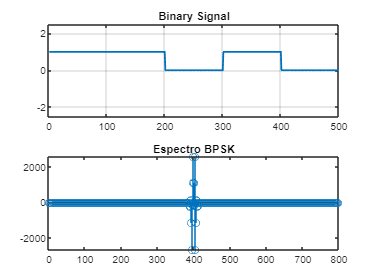

% CONVOLUTION WITH THE WINDOW
time_recover_signal = 1:1:800;
res = conv(bpsk_signal,filtro_rsine);
stem(time_recover_signal, res);
title('Señal Convolucionada con Filtro Cos^2');
 % graficado en frecuencia
stem(time_recover_signal, real(ttof(res)));
title('Espectro BPSK');

% freq to time
bpsk_signal_time = real(ftot(res))

bpsk_signal_time =    -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000


## Demodulacion BPSK

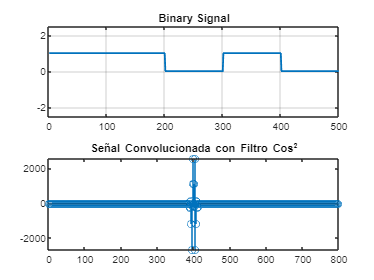

time_recover_signal_0 = 1:1:500;
stem(time_recover_signal_0, real(ttof(res)));
title('Señal Convolucionada con Filtro Cos^2');


% banda acceso = .5
% 1 simbolo por segundo
g_f = 0; % espectro frecuencias filtro formador
tau = 0 ;
w = 1/tau; % ancho de banda normalizado w= 1/tau
b = w(1+aplha); %ancho de banda
alpha = 0; % ancho de banda en exceso B=W(1+ALPHA) 
f1 = 2*w-b; % diferencia entre b y 2w



% Multiplicacion señal modulada amplitud
% portadora 25 Hz

## Demodulacion Coherente BPSK

% multiplicacion y filtrado
% corrimiento de pase portadora pi/4, pi/2, 3pi/4 y pi
% desviacion frecuencia .1Hz
% observaciones

## Filtro Pasa bajas Hamming